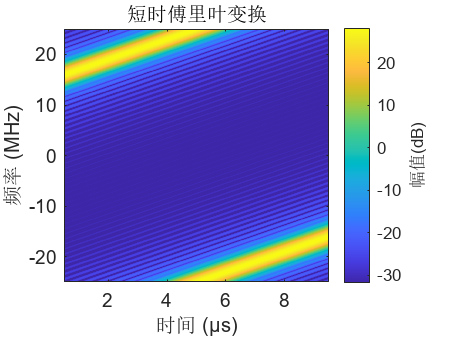

%question 1
clear;
fs=50*1e6;
t=0:1/fs:0.00001-1/fs;
f_start1=15*1e6;
f_stop1=35*1e6;
x1=chirp(t,f_start1,t(end),f_stop1,'linear',0,'complex');
win = hamming(50,"periodic");
stft(x1,fs,Window=kaiser(50,5),OverlapLength=49,FFTLength=1024);

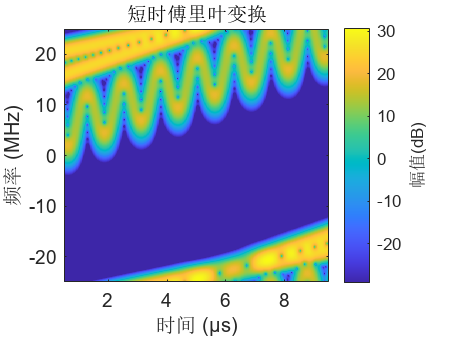

%question 2
clear;
load("wave_data.mat");
fs=50*1e6;
t=0:1/fs:0.00001-1/fs;
f_start1=15*1e6;
f_stop1=35*1e6;
f_start2=20*1e6;
f_stop2=32*1e6;
x1=chirp(t,f_start1,t(end),f_stop1,'linear',0,'complex');
x2=chirp(t,f_start2,t(end),f_stop2,'linear',0,'complex');
y=x1+x2+wave_data;
figure;
stft(y,fs,Window=kaiser(50,10),OverlapLength=49,FFTLength=1024*4);

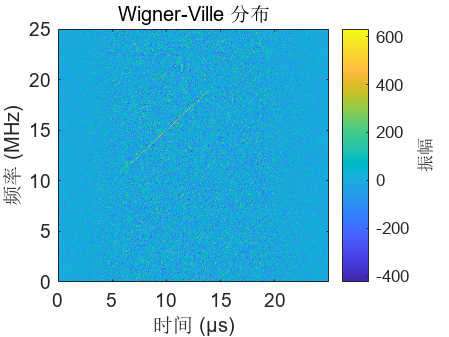

%question 3.1
clear;
fs=50*1e6;
t=0:1/fs:0.00001-1/fs;
f_start1=10*1e6;
f_stop1=20*1e6;
x1=chirp(t,f_start1,t(end),f_stop1,'linear',0,'complex');
x2=zeros(1,250);
y=awgn([x2,x1,x2,x2],-5);
[d,F,T]=wvd(y,fs);
figure;
wvd(y,fs);

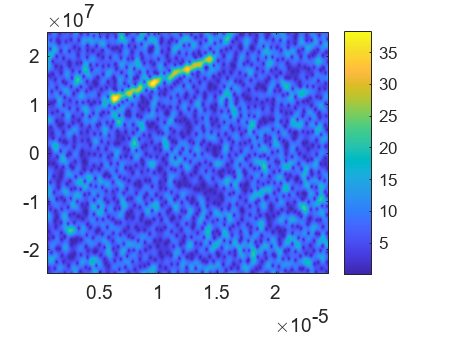

figure;
[s,f,time] = stft(y,fs,Window=kaiser(50,5),OverlapLength=49,FFTLength=1024);
figure;
imagesc(time,f,abs(s))
axis xy
colorbar

theta=0:179;
[R,xp] = radon(d,theta);
[a,b]=find(R==max(max(abs(R))))

a = 1175

b = 64

k1=1.96/tan(theta(b)/180*pi);
s=smoothdata(abs(s));
[m,n]=find(s/max(max(s))>0.68)

m =    739
   740
   741
   742
   743
   744
   745
   746
   747
   748


n =    274
   274
   274
   274
   274
   274
   274
   274
   274
   274


t1=time(min(n));
t2=time(max(n));
f1=f(min(m));
f2=f(max(m));
k2=(f2-f1)/(t2-t1)*1e12;

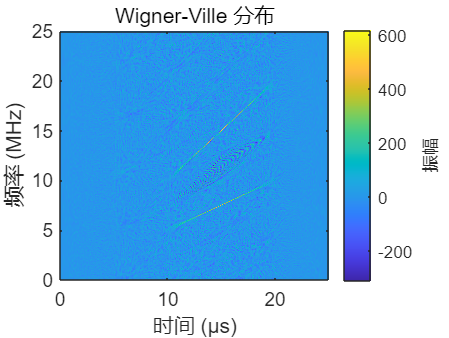

%question 3.2
clear;

%生成含噪声的多个LFM信号
fs=50*1e6;
t1=0:1/fs:0.00001-1/fs;
f_start1=10*1e6;
f_stop1=20*1e6;
x1=chirp(t1,f_start1,t1(end),f_stop1,'linear',0,'complex');
f_start2=5*1e6;
f_stop2=10*1e6;
t2=0:1/fs:0.00001-1/fs;
x2=chirp(t2,f_start2,t2(end),f_stop2,'linear',0,'complex');
n=zeros(1,250);
y=awgn([n,n,x1+x2,n],0);

%通过wvd变换得到时频图象
[d,F,T]=wvd(y,fs);
figure;
wvd(y,fs);

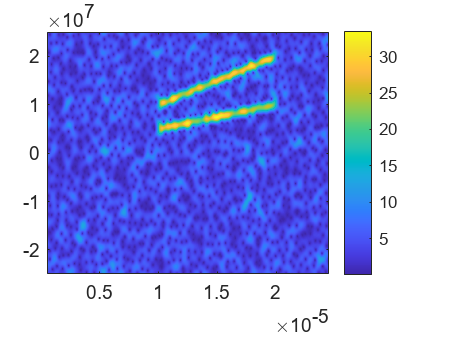

%对时频图象进行radon变换，其极大值对应的旋转角度和LFM的斜率存在映射关系
theta=0:179;
[R,xp] = radon(d,theta);
%zig_zag排序，寻找极大值求斜率
temp=sort(R);
temp=sort(temp,2);
a=temp(end,end);
[A1,B1]=find(R==a);
k1=1.96/tan(theta(B1)/180*pi);
B2=B1;

cc=0;
zig_zag=[1,0;0,1;0,2;1,1;2,0;3,0;2,1;1,2;0,3];
while abs(B2-B1)<10
    cc=cc+1;
    if(cc==10)
        break;
    end
    b=temp(end-zig_zag(cc,1),end-zig_zag(cc,2));
    [A2,B2]=find(R==b);
end
k2=1.96/tan(theta(B2)/180*pi);

%斜率已知，做stft，得到时频图象
figure;
[s,f,time] = stft(y,fs,Window=kaiser(50,5),OverlapLength=49,FFTLength=1024);
imagesc(time,f,abs(s))
axis xy
colorbar


%设定阈值，取出频率分量较大的点
[h,r]=find(abs(s)/max(max(abs(s)))>0.7);
f_temp=f(h);
t_temp=time(r);
flag1=zeros(1,length(h));
tongji=zeros(1,length(h));
%以一定的间隔求这些点之间的斜率，并与前面得到的斜率比对
%和k1差小于0.1的flag2改为1,和k2差小于0.1的flag2改为2
%不在此范围内的flag2保持0
%对flag2求和，值大于0的认为点在k1这条线上，反之在k2上
for i=1:length(h)
    flag2=zeros(1,length(h));
    for j=1:length(h)
        if(abs(j-i)>length(h)/3)
            delta_f=f_temp(i)-f_temp(j);
            delta_t=t_temp(i)-t_temp(j);
            if(delta_t~=0 && abs(delta_f/delta_t/1e12-k1)<0.2)
                flag2(j)=1;
            else
                if(delta_t~=0 && abs(delta_f/delta_t/1e12-k2)<0.2)
                    flag2(j)=-1;
                end
            end
        end
    end
    tongji(i)=sum(flag2);
    if(sum(flag2)>0)
        flag1(i)=1;
    else
        flag1(i)=2;
    end
end
%将k1,k2两条直线上的点取出，根据点在stft中的信息获取其他参数
f_new1=f_temp(flag1==1);
f_new2=f_temp(flag1==2);
t_new1=t_temp(flag1==1);
t_new2=t_temp(flag1==2);

f_start2_test=min(f_new1);
f_stop2_test=max(f_new1);
f_start1_test=min(f_new2);
f_stop1_test=max(f_new2);

t_start1_test=min(t_new1);
t_stop1_test=max(t_new1);
t_start2_test=min(t_new2);
t_stop2_test=max(t_new2);